# Computer exercise 1

## 1  Introduction to estimation of expected value, covariance function and spectral density

### 1.1 Estimation of expected value 

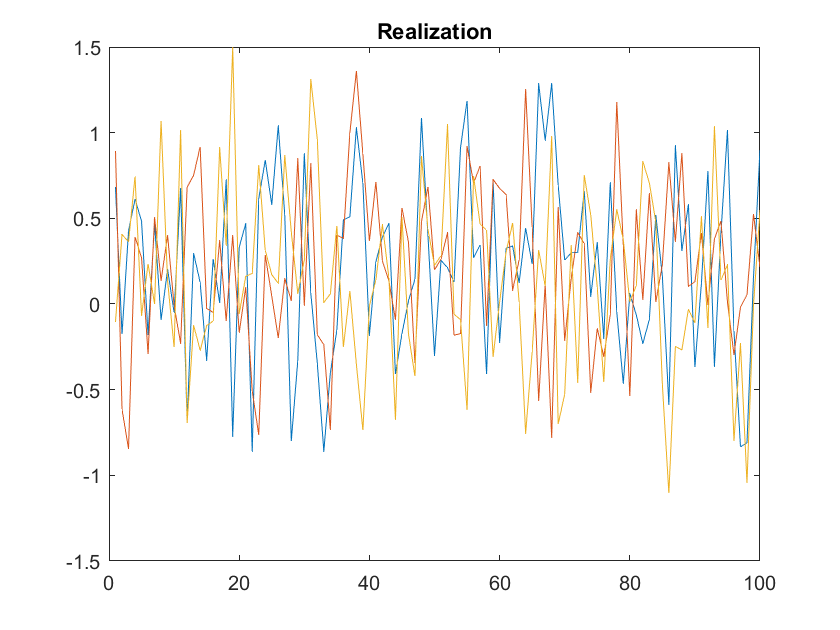

load data.mat;
figure(1)
plot([data1 data2 data3]);
title("Realization")

m=[mean(data1) mean(data2) mean(data3)];


**Q1**: Smilar mean, similar variance. Not really zero mean

% We calculate the confidence intervall
variance= 0.25;
n= length(data1);
d = [norminv(0.025) norminv(0.975)].*(sqrt(variance)./sqrt(n));
I = [m(1)+d; m(2)+d; m(3)+d]

I =     0.1232    0.3192
    0.1280    0.3240
    0.0550    0.2510


**Q2**: We find that none include 0 in the confidence intervall.

% Assuming same process we calculate the mean
mean_all= mean(m)

mean_all = 0.2001

**Q3**: Final mean: 0.2001

### 1.2 Estimation of covariance function

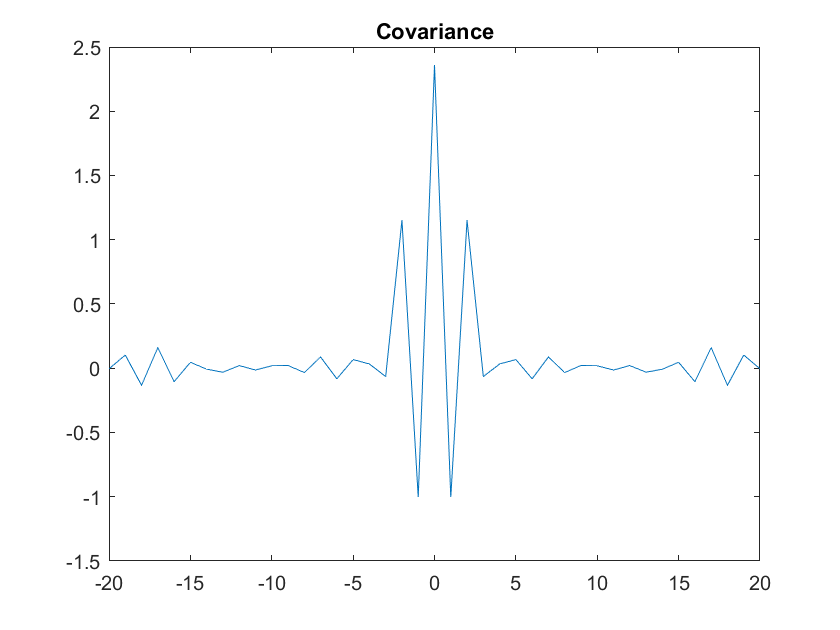

%Estimating covarience function
load data2.mat
[r,lags]=xcov(y,20,'biased');
plot(lags,r)
title("Covariance")

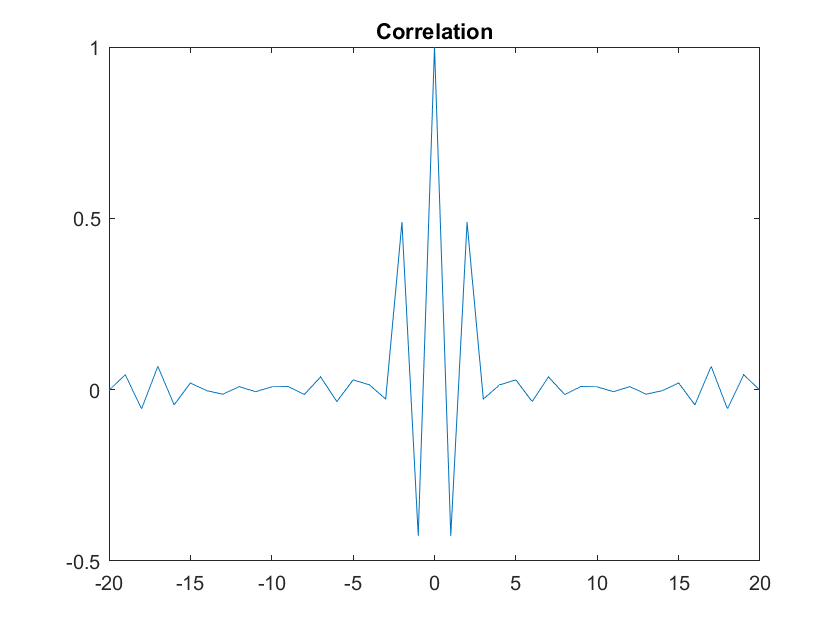

%Estimating correlation function
[rho,lags]=xcov(y,20,'coeff');
figure(3)
plot(lags,rho)
title("Correlation")

**Q4**: $\rho(\tau)= \frac{r(\tau)}{r(0)} $

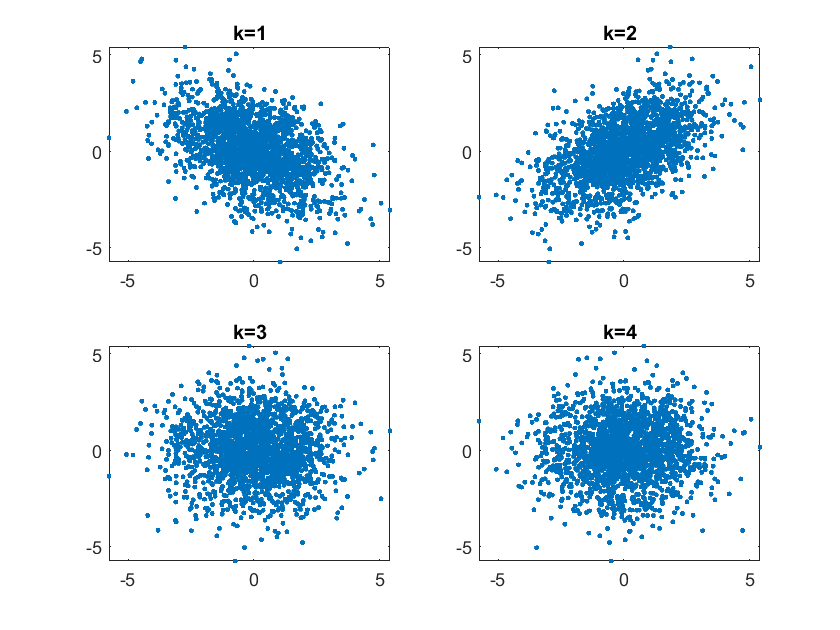

%ploting y(t) and y(t-k) for k=1,2,3,4
for k=1:4
    subplot(2,2, k);
    plot(y(1:end-k),y(k+1:end),'.');
    title("k=" + k)
end

**Q5:** We are essentially plotting the correlation for different $\tau=k$, for k=1, we see we have negative correlation, which is also seen in the correlation plot.  For k=2, we see we have positive correlation, which is also seen in the correlation plot, etc.

### 1.3 Estimation of spectral density

A1 = 1.1675

A2 = 2.1396

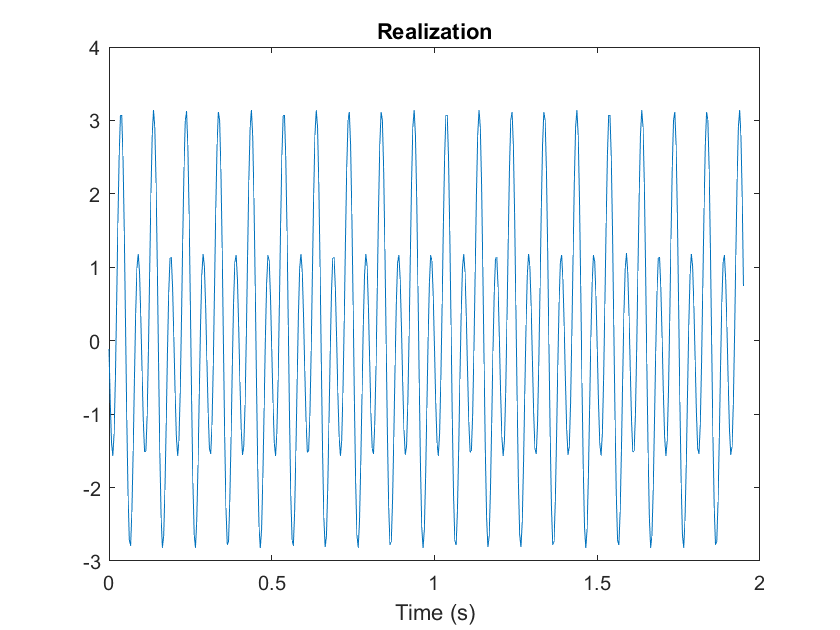

signalsim

**Q6: **$T_{max}=\frac{N-1}{f_s}$

%Estimating covarience function with maxlag N-1
T_max= (N-1)./fs

T_max = 1.9492

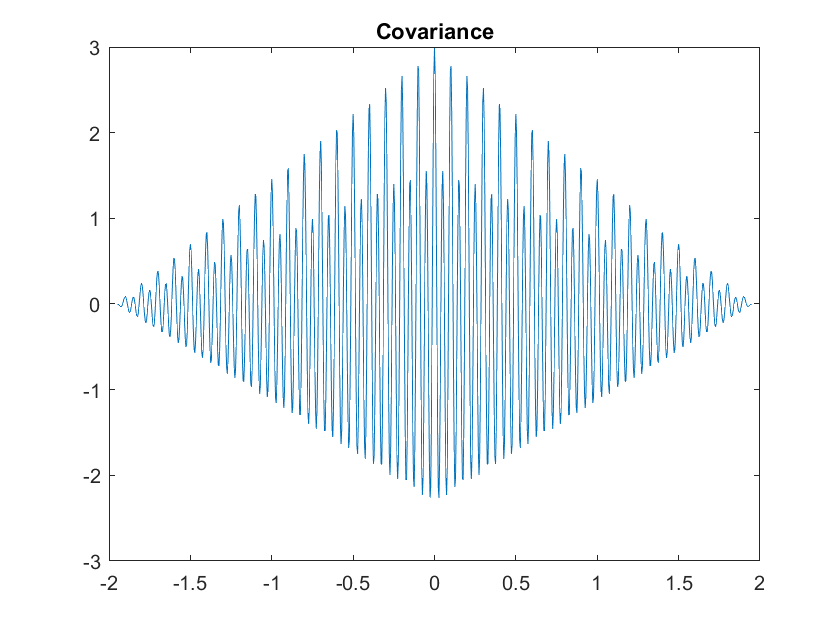

[r,lags]=xcov(x,N-1,'biased');
t2= lags./fs;
plot(t2,r) %x axis in seconds
title("Covariance")

**Q7**: They do have the same periodicity.

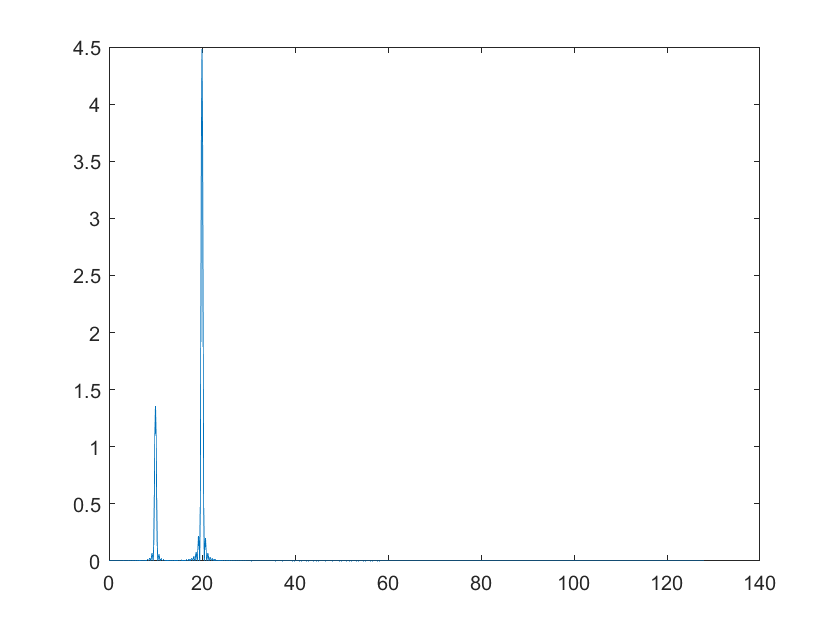

%Estimating the spectral density with the periodogram
NFFT=2048;
[R,f]=periodogram(x,[],NFFT,fs);
plot(f, R)

title('Spectogram')

**Q8: **The frequency peaks are at the same frequency that the covariance and realization have. 10, 20 Hz. 

**Q9:** This is because the height of the peak is connected to how present a frequency is. Since A is a stochastic variable the strength of each frequency will vary.

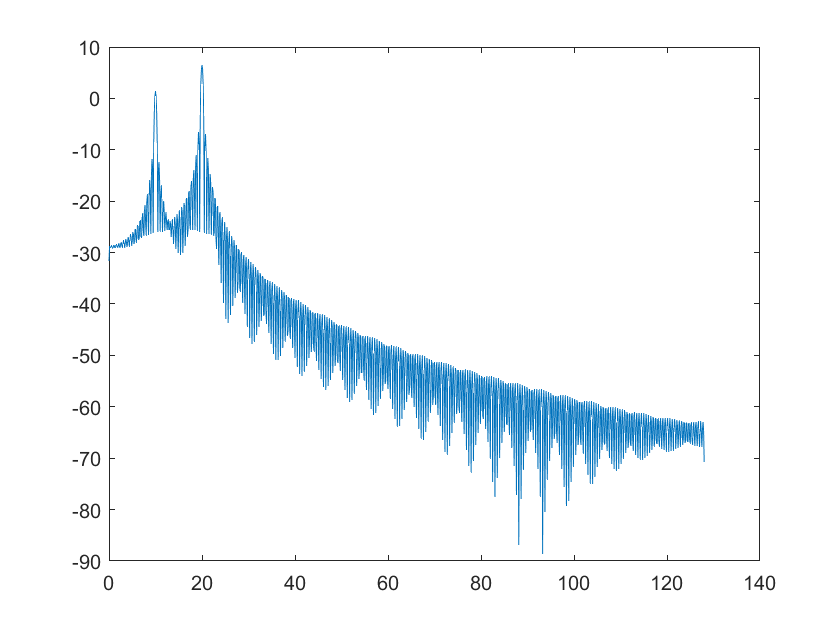

plot(f,10*log10(R))

title('Spectogram (DB)')

**Q10**: The db-scale helps us catch details otherwise too small to see.

## 2 Instruments in a symphony orchestra 

### 2.1 Keynotes and overtones 

load cellodiffA.mat
fs=44100

fs = 44100

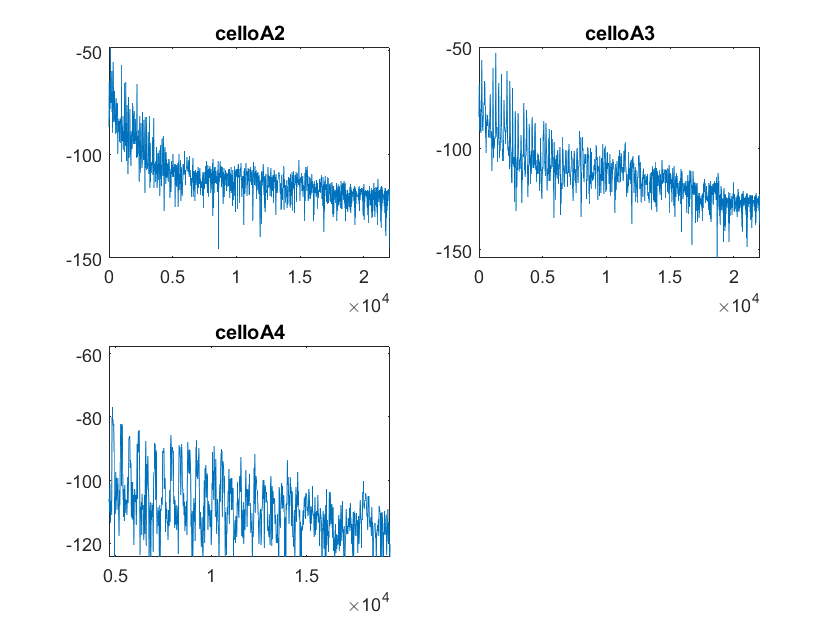

sound(celloA2, fs)
% sound(celloA3, fs)
% sound(celloA4, fs)

%Ploting spectrogram for each case
NFFT=2048;
subplot(2,2, 1);
[R,f]=periodogram(celloA2,[],NFFT,fs);
plot(f, 10*log10(R))
title('celloA2')

subplot(2,2, 2);
[R,f]=periodogram(celloA3,[],NFFT,fs);
plot(f, 10*log10(R))
title('celloA3')

subplot(2,2, 3);
[R,f]=periodogram(celloA4,[],NFFT,fs);
plot(f, 10*log10(R))
title('celloA4')

**Q11:** A2: 107,215, 323..., A3: 215, 430, 667..., A4: 450, 882, 1334

Seems like the frequency structure somewhat matches the simple overtone-model described. We hear that A2 has a deeper tone (lower), and a higher tone in A3 and even higher in A4, which is ecpected considering are results.